# Práctica 3: Grafos.

Equipo: Miguel Egido Morales y Alfredo Robledano Abasolo

Grupo: 3ºB

El objetivo de esta práctica es programar el algoritmo de Kruskal mediante un código de tipo function. Para ello subdividiremos el problema en problemas más pequeños. Para ello recuerda que el objetivo es encontrar un subgrafo **CONEXO** $S=(V(G),C)$ del grafo $G=(V(G),E(G))$ tal que $C$ fuera un conjunto conectador. Para ello, la idea es ir añadiendo aristas al grafo $G'=(V(G),\{\})$ hasta conseguir la propiedad de finalización del algoritmo de Kruskal cumpliendo el resto de pasos.

Recordemos que un grafo $G=(V(G),E(G))$ se podía dar por su matriz de adyacencia $A=Ad(G)$.

## **Problema 1**

Crea un código del tipo function cuyos inputs sean la matriz de adyacencia de un grafo $G$ y un vértice $e=\{i,j\}\in E(G)$ (el cual se puede representar por la entrada $(i,j)=(j,i)$ de la matriz $A$) y sus outputs sean un array de carácteres especificando si dicha arista pertenecía a un ciclo (no trivial) o no. Nótese que si no existe dicha arista debe dar el mensaje de error correspondiente y que si $A=Ad(G)$ no es una matriz correspondiente a una de adyancencia debe dar error también.

### Respuesta 1

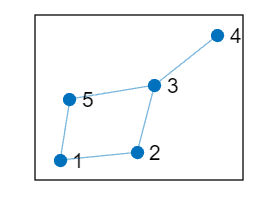

clear, clc, clf

A = [
    0, 1, 0, 0, 1;
    1, 0, 1, 0, 0;
    0, 1, 0, 1, 1;
    0, 0, 1, 0, 0;
    1, 0, 1, 0, 0;
];

G = graph(A);
figure
plot(G)

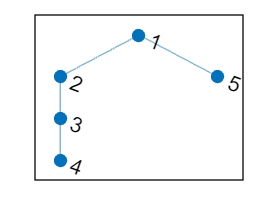

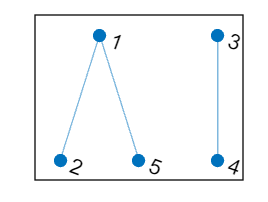

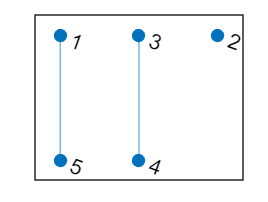

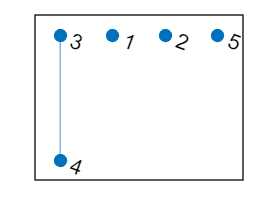


arista = [3, 5];

res = perteneceCiclo(A, arista);


disp(res);

   1



## **Problema 2**

Crea un código del tipo function cuyos inputs sean la matriz de adyacencia de un grafo $G$ y sus outputs sean un array de carácteres indicando si el grafo es conexo o no.

### Respuesta 2

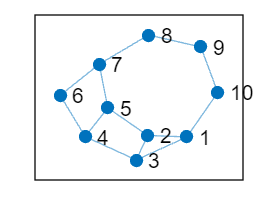

clear, clc, clf
% Ejemplo conexo
A = [
    0 1 1 0 0 0 0 0 0 1;
    1 0 1 0 1 0 0 0 0 0;
    1 1 0 1 0 0 0 0 0 0;
    0 0 1 0 1 1 0 0 0 0;
    0 1 0 1 0 0 1 0 0 0;
    0 0 0 1 0 0 1 0 0 0;
    0 0 0 0 1 1 0 1 0 0;
    0 0 0 0 0 0 1 0 1 0;
    0 0 0 0 0 0 0 1 0 1;
    1 0 0 0 0 0 0 0 1 0;
];


G = graph(A);
figure
plot(G)

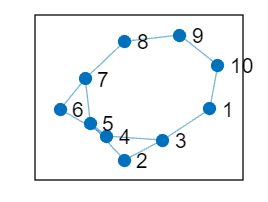

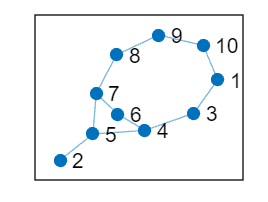

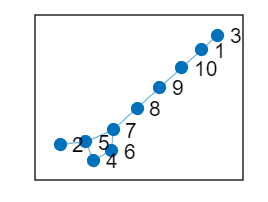

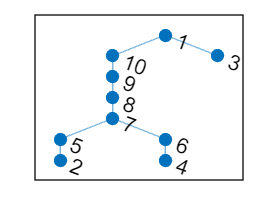

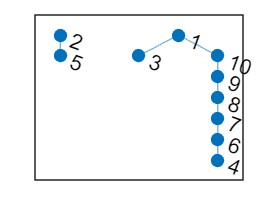

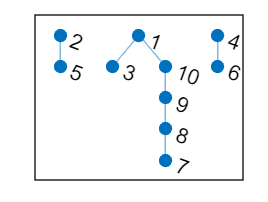

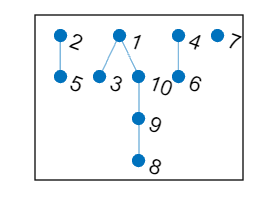

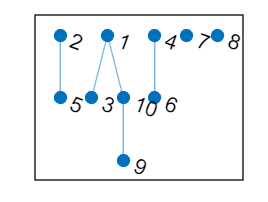


resultado = esConexo(A);

disp(resultado);

   1



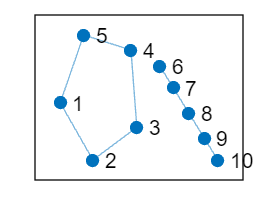


% ejemplo no conexo
B = [
    0 1 0 0 1 0 0 0 0 0;
    1 0 1 0 0 0 0 0 0 0;
    0 1 0 1 0 0 0 0 0 0;
    0 0 1 0 1 0 0 0 0 0;
    1 0 0 1 0 0 0 0 0 0;
    0 0 0 0 0 0 1 0 0 0;
    0 0 0 0 0 1 0 1 0 0;
    0 0 0 0 0 0 1 0 1 0;
    0 0 0 0 0 0 0 1 0 1;
    0 0 0 0 0 0 0 0 1 0;
];



P = graph(B);
figure
plot(P)

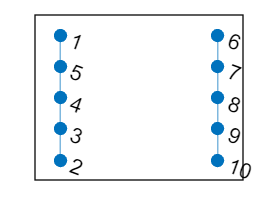

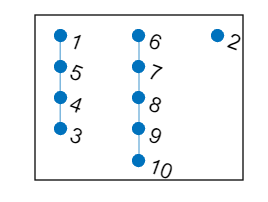

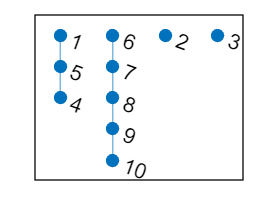

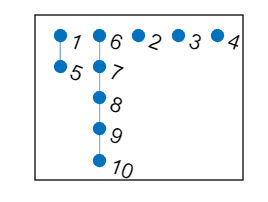

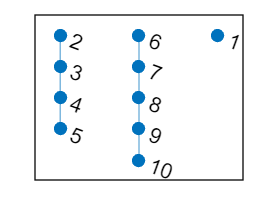


res = esConexo(B);

disp(res);

   0



## **Problema 3**

Crea un código del tipo function cuyos inputs sean la matriz de adyacencia de un grafo $G$ y la matriz $\Omega(G)$ de pesos de $G$ y sus outputs sean o bien la matriz de adyacencia de $S=(V(G),C)$ o bien una matriz $1\times 2$ donde $a_{11}$ sea una matriz $1\times n$ cuyos elementos son números y $n$ el número de vértices a calcular y $a_{12}$ se una matriz $1\times m$ cuyos elementos son matrices $1\times 2$ representando los vértices. (Podéis elegir la opción que prefiaráis).

Pista: Crea una matriz $1\times k$ cuyos elementos sean las aristas de $G$ ordenadas por peso. Nótese que los elementos de esta matriz son matrices $1\times 2$.

### Respuesta 3

#### Funciones ejercicios 1 y 2

function res = perteneceCiclo(A, arista)
    % Dimensiones matriz de adyacencia
    [fil, col] = size(A);
    num_nodos = fil;
    % Matriz de adyacencia debe ser:
    if ~(fil == col ... % Cuadrada
        && isequal(A, A')) % Simétrica

        disp('Error: Matriz de adyacencia no válida');
        res = -1;
        return
    end

    % La arista debe tener:
    if ~(length(arista) == 2 ... % Dos componentes
        && all(arista == round(arista)) ... % Valores enteros
        && arista(1) ~= arista(2) ... % No ciclos propios
        && all(arista >= 1 & arista <= num_nodos)) % Valores entre 1 y nº de aristas

        disp('Error: Arista no válida');
        res = -1;
        return
    end
    
    % Se elimina la arista que queremos comprobar
    A(arista, flip(arista)) = 0;

    % Si se puede ir de uno de sus extremos al otro tras eliminarla del grafo inicial
    % Entonces la arista pertenece a un ciclo 
    [res, ~] = dfs(A, arista(1), arista(2));
end


function res = esConexo(A)
% Esta funcion comprueba si e grafo es conexo o no.
    [fil, col] = size(A);
    % Matriz de adyacencia debe ser:
    if ~(fil == col ... % Cuadrada
        && isequal(A, A')) % Simétrica

        disp('Error: Matriz de adyacencia no válida');
        res = false;
        return
    end
    
    % De manera arbitraria elegimos el primer nodo para comenzar a explorar
    actual = 1;

    % Exploramos todo el grafo (no hay objetivo, que equivale a objetivo=0)
    objetivo = 0;
    
    % Exploración
    [~, visitados] = dfs(A, actual, objetivo);
    
    % Si desde cualquier nodo alcanzamos el resto, el grafo es conexo
    res = all(visitados);
end


function [pertenece_comp_conexa, visitados] = dfs(grafo, actual, objetivo, visitados)
    % Por defecto no se ha visitado ningún nodo
    % (En el caso de no especificar la variable "visitados")
    if nargin < 4
        % Se especifica el vector de nodos visitados
        num_nodos = size(A, 1);
        visitados = zeros(1, num_nodos);
    end

    % En cada llamada recursiva el nodo actual se visita
    visitados(actual) = 1;

    % Vecinos al nodo actual
    vecinos = grafo(actual, :);

    % A los nodos vecinos les restamos a los vecinos los que ya hemos visitado
    vecinos_no_visitados = find(vecinos - (vecinos & visitados));
    figure
    plot(graph(grafo))

    % Si el objetivo toma valor 0 (No hay objetivo)
    % Se recorre toda la componente conexa del nodo actual
    if ~objetivo

        % Si no hay objetivo no hablamos de pertenecer a la componente
        pertenece_comp_conexa = -1;

        for i = 1:length(vecinos_no_visitados)
            % Eliminamos la arista que hemos utilizado para visitar
            arista = [actual, vecinos_no_visitados(i)];
            grafo(arista, flip(arista)) = 0;
    
            % Por recursión se siguen visitando
            [~, visitados] = dfs(grafo, vecinos_no_visitados(i), objetivo, visitados);
        end

    % Si existe objetivo el algoritmo se detiene al encontrarlo
    else

        % Inicialmente suponemos que el objetivo no pertenece
        pertenece_comp_conexa = false;

        for i = 1:length(vecinos_no_visitados)
            % Finaliza la recursión si hemos visitado al objetivo
            if ismember(objetivo, find(visitados))
                pertenece_comp_conexa = true;
                break
            end
    
            % Eliminamos la arista que hemos utilizado para visitar
            arista = [actual, vecinos_no_visitados(i)];
            grafo(arista, flip(arista)) = 0;
    
            % Por recursión se siguen visitando
            [pertenece_comp_conexa, visitados] = dfs(grafo, vecinos_no_visitados(i), objetivo, visitados);
            
            % Finalizamos la exploración si se encuentra el objetivo
            if pertenece_comp_conexa
                break
            end
        end
    end
end